% Section A: Square Wave Synthesis

% Parameters
T = 1;          % Period (seconds)
t = -T/2:0.001:T/2;  % Time vector, small steps for smooth plot
N = [1 3 5 7 9];     % Harmonic components

% Preallocate arrays for different harmonic sums
y1 = zeros(1,length(t));    % 1+3
y2 = zeros(1,length(t));    % 1+3+5
y3 = zeros(1,length(t));    % 1+3+5+7
y4 = zeros(1,length(t));    % 1+3+5+7+9

% Calculation loop
for i = 1:length(N)
    n = N(i);
    An = 4/(n*pi);  % Fourier coefficient for square wave
    harm = An*cos(2*pi*n*t/T);
    
    y1 = y1 + (i<=2)*harm;  % First 2 terms
    y2 = y2 + (i<=3)*harm;  % First 3 terms
    y3 = y3 + (i<=4)*harm;  % First 4 terms
    y4 = y4 + harm;         % All terms
end

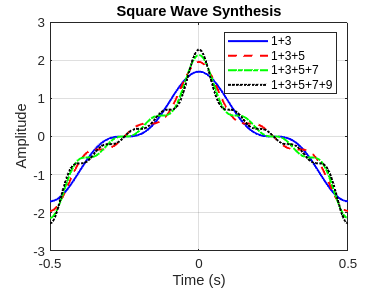

% Plot
figure
plot(t, y1, 'b-', t, y2, 'r--', t, y3, 'g-.', t, y4, 'k:', 'LineWidth', 1.5)
grid on
legend('1+3', '1+3+5', '1+3+5+7', '1+3+5+7+9')
xlabel('Time (s)')
ylabel('Amplitude')
title('Square Wave Synthesis')